# **Linear and Extended Kalman Filter Design for a Pendulum System**

**Clear all, add path, open Simulink model**

clear;
clf;
clc;
addpath("helperFunctions");
open_system("models/virtualPendulumModel");

## Kalman Filter to estimate the angular position of the linearized pendulum system

model.ts = 0.01; % Sampling time [s]
model.m = 1; % Pendulum mass [kg]
model.L = 1; % Pendulum length [m]
model.g = 9.81; % Gravity [m/s^2]

% Pendulum IC
model.theta0 = pi/18; 
model.theta_dot0 = 0;

The **continuous-time** pendulum system model is:


$$\dot{\theta} = \dot{\theta} \\
\ddot{\theta} = -\frac{g}{L}sin(\theta) + \frac{1}{mL^2}\tau$$


The **linearized continuous-time** model is:


$$A_c = \pmatrix{0 & 1 \cr -\frac{g}{L} & 0} ,\quad B_c = \pmatrix{0 \cr \frac{1}{mL^2}}, \quad C_c = \pmatrix{1 & 0 }, \quad D_c = 0$$


% Linearized continuos-time SS model
model.con_lin.A = [0 1;
     -model.g/model.L 0];
model.con_lin.B = [0;
     1];
model.con_lin.C = [1 0];
model.con_lin.D = 0;

By applying forward euler transformation,


$$\dot{\theta} \approx \frac{\theta_{k+1} - \theta_k}{T_s}$$


the corresponding **discrete-time** pendulum system model can be found:


$$\theta_{k+1} = \theta_k + T_s \omega_k \\
\omega_{k+1} = \omega_k -T_s\frac{g}{L}sin(\theta_k) + \frac{T_s}{mL^2}\tau_k$$


The **linearized discrete-time** model is:


$$A_d = \pmatrix{1 & T_s \cr -T_s\frac{g}{L} & 1} ,\quad B_d = \pmatrix{0 \cr \frac{T_s}{mL^2}}, \quad C_d = \pmatrix{1 & 0 }, \quad D_d = 0$$


% Linearized discrete-time SS model
model.dis_lin.A = [1 model.ts;
     -model.ts*model.g/model.L 1];
model.dis_lin.B = [0;
     model.ts];
model.dis_lin.C = [1 0];
model.dis_lin.D = 0;

% Process noise
model.Q = diag([0 1e-3]);
model.R = 1e-4;

% Initial state and covariance estimates
model.dis_lin.x0est = [model.theta0; model.theta_dot0];
model.dis_lin.P0 = diag([1 1]);

### **Visualize the motion of the pendulum (No process noise)**

% Set parameters
model.simTime = 3;
set_param("virtualPendulumModel/Process noise", "Cov", "0");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.1983
   -0.0192

EKF
    0.1983
   -0.0145

KF
    0.1764
   -1.1228

EKF
    0.1765
   -1.1195

KF
    0.1795
   -0.4259

EKF
    0.1795
   -0.4246

KF
    0.1752
   -0.4461

EKF
    0.1752
   -0.4452

KF
    0.1695
   -0.5030

EKF
    0.1695
   -0.5025

KF
    0.1634
   -0.5492

EKF
    0.1634
   -0.5489

KF
    0.1642
   -0.4200

EKF
    0.1642
   -0.4183

KF
    0.1661
   -0.3125

EKF
    0.1661
   -0.3091

KF
    0.1657
   -0.2800

EKF
    0.1658
   -0.2760

KF
    0.1658
   -0.2492

EKF
    0.1659
   -0.2445

KF
    0.1652
   -0.2362

EKF
    0.1653
   -0.2312

KF
    0.1623
   -0.2603

EKF
    0.1624
   -0.2561

KF
    0.1635
   -0.2256

EKF
    0.1636
   -0.2199

KF
    0.1590
   -0.2707

EKF
    0.1591
   -0.2670

KF
    0.1506
   -0.3575

EKF
    0.1506
   -0.3577

KF
    0.1447
   -0.4011

EKF
    0.1447
   -0.4028

KF
    0.1475
   -0.3325

EKF
    0.1476
   -0.3297

KF
    0.1440
   -0.3492

EKF
    0.1440
   -0.3468

KF
    0.1392
   -0.3785

EKF
    0.1393
   -0


% Plot system response
animatePendulum(simOut.tout, simOut.theta.signals(1).values, [], [], rad2deg(model.theta0));

### Compare measured to actual pendulum response (No process noise)

% Set parameters
model.simTime = 5;
set_param("virtualPendulumModel/Process noise", "Cov", "0");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.1983
   -0.0192

EKF
    0.1983
   -0.0145

KF
    0.1764
   -1.1228

EKF
    0.1765
   -1.1195

KF
    0.1795
   -0.4259

EKF
    0.1795
   -0.4246

KF
    0.1752
   -0.4461

EKF
    0.1752
   -0.4452

KF
    0.1695
   -0.5030

EKF
    0.1695
   -0.5025

KF
    0.1634
   -0.5492

EKF
    0.1634
   -0.5489

KF
    0.1642
   -0.4200

EKF
    0.1642
   -0.4183

KF
    0.1661
   -0.3125

EKF
    0.1661
   -0.3091

KF
    0.1657
   -0.2800

EKF
    0.1658
   -0.2760

KF
    0.1658
   -0.2492

EKF
    0.1659
   -0.2445

KF
    0.1652
   -0.2362

EKF
    0.1653
   -0.2312

KF
    0.1623
   -0.2603

EKF
    0.1624
   -0.2561

KF
    0.1635
   -0.2256

EKF
    0.1636
   -0.2199

KF
    0.1590
   -0.2707

EKF
    0.1591
   -0.2670

KF
    0.1506
   -0.3575

EKF
    0.1506
   -0.3577

KF
    0.1447
   -0.4011

EKF
    0.1447
   -0.4028

KF
    0.1475
   -0.3325

EKF
    0.1476
   -0.3297

KF
    0.1440
   -0.3492

EKF
    0.1440
   -0.3468

KF
    0.1392
   -0.3785

EKF
    0.1393
   -0

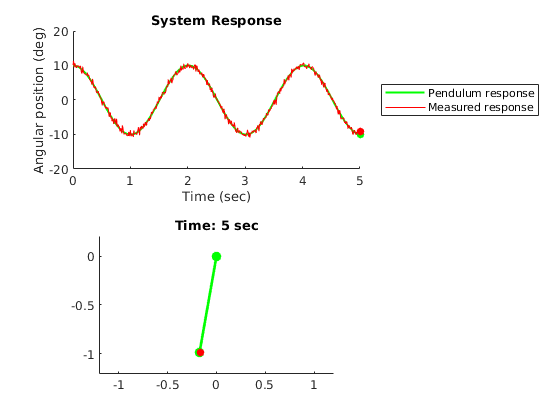


% Plot system response
animatePendulum(simOut.tout, simOut.theta.signals(1).values, simOut.theta.signals(2).values, [], rad2deg(model.theta0));

### Compare measured, actual and estimated pendulum response 

% Set parameters
model.simTime = 5;
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.1983
   -0.0192

EKF
    0.1983
   -0.0145

KF
    0.1765
   -1.1226

EKF
    0.1765
   -1.1193

KF
    0.1795
   -0.4255

EKF
    0.1795
   -0.4242

KF
    0.1752
   -0.4455

EKF
    0.1752
   -0.4446

KF
    0.1695
   -0.5023

EKF
    0.1695
   -0.5018

KF
    0.1634
   -0.5484

EKF
    0.1634
   -0.5481

KF
    0.1642
   -0.4192

EKF
    0.1642
   -0.4175

KF
    0.1662
   -0.3117

EKF
    0.1662
   -0.3083

KF
    0.1658
   -0.2792

EKF
    0.1658
   -0.2752

KF
    0.1659
   -0.2484

EKF
    0.1659
   -0.2437

KF
    0.1653
   -0.2354

EKF
    0.1654
   -0.2304

KF
    0.1624
   -0.2594

EKF
    0.1625
   -0.2553

KF
    0.1636
   -0.2248

EKF
    0.1637
   -0.2191

KF
    0.1591
   -0.2699

EKF
    0.1592
   -0.2661

KF
    0.1507
   -0.3566

EKF
    0.1508
   -0.3568

KF
    0.1448
   -0.4002

EKF
    0.1448
   -0.4018

KF
    0.1476
   -0.3316

EKF
    0.1477
   -0.3287

KF
    0.1441
   -0.3483

EKF
    0.1442
   -0.3459

KF
    0.1394
   -0.3776

EKF
    0.1394
   -0

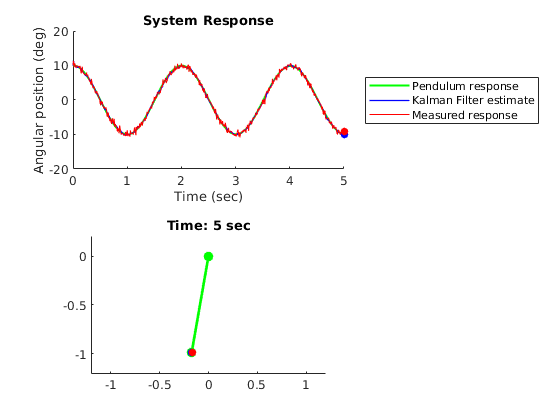


% Plot system response
animatePendulum(simOut.tout, simOut.theta.signals(1).values, simOut.theta.signals(2).values, simOut.theta.signals(3).values, rad2deg(model.theta0));

### Angular IC: pi/16, pi/14

% Initial true state, state and covariance estimates
model.simTime = 2;
model.theta0 = pi/16;
model.lin.x0est = [pi/18; model.theta_dot0];
model.lin.P0 = diag([1 1]);

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.2201
   -0.0211

EKF
    0.2201
   -0.0122

KF
    0.1982
   -1.1270

EKF
    0.1983
   -1.1209

KF
    0.2012
   -0.4324

EKF
    0.2013
   -0.4296

KF
    0.1968
   -0.4548

EKF
    0.1969
   -0.4531

KF
    0.1911
   -0.5138

EKF
    0.1911
   -0.5128

KF
    0.1848
   -0.5620

EKF
    0.1848
   -0.5614

KF
    0.1855
   -0.4350

EKF
    0.1855
   -0.4330

KF
    0.1873
   -0.3295

EKF
    0.1874
   -0.3259

KF
    0.1867
   -0.2991

EKF
    0.1868
   -0.2949

KF
    0.1866
   -0.2703

EKF
    0.1867
   -0.2654

KF
    0.1859
   -0.2593

EKF
    0.1860
   -0.2541

KF
    0.1827
   -0.2854

EKF
    0.1828
   -0.2810

KF
    0.1836
   -0.2527

EKF
    0.1838
   -0.2468

KF
    0.1789
   -0.2997

EKF
    0.1790
   -0.2958

KF
    0.1702
   -0.3884

EKF
    0.1702
   -0.3883

KF
    0.1640
   -0.4338

EKF
    0.1640
   -0.4352

KF
    0.1664
   -0.3671

EKF
    0.1665
   -0.3640

KF
    0.1626
   -0.3856

EKF
    0.1627
   -0.3830

KF
    0.1575
   -0.4167

EKF
    0.1576
   -0

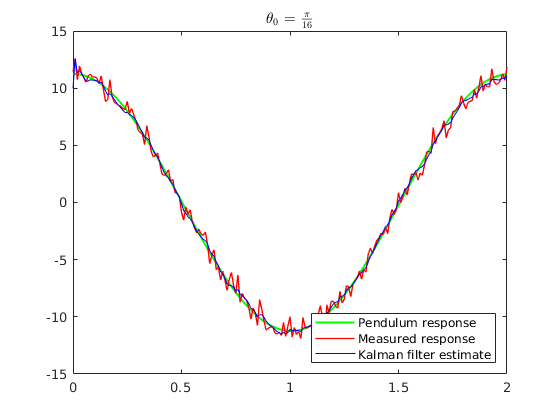


% Plot system response
figure(4);
plot(simOut.tout, simOut.theta.signals(1).values, 'g', LineWidth = 1.5);
hold on;
plot(simOut.tout, simOut.theta.signals(2).values, 'r', LineWidth = 1);
hold on;
plot(simOut.tout, simOut.theta.signals(3).values, 'b', LineWidth = 0.5);
title('$\theta_0$ = $\frac{\pi}{16}$', 'interpreter','latex');
legend('Pendulum response', 'Measured response', 'Kalman filter estimate', 'Location','southeast');
hold off;

% Initial true state, state and covariance estimates
model.theta0 = pi/14;
model.lin.x0est = [pi/18; model.theta_dot0];
model.lin.P0 = diag([1 1]);

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.2482
   -0.0236

EKF
    0.2482
   -0.0092

KF
    0.2262
   -1.1327

EKF
    0.2263
   -1.1228

KF
    0.2292
   -0.4413

EKF
    0.2292
   -0.4366

KF
    0.2247
   -0.4667

EKF
    0.2247
   -0.4640

KF
    0.2188
   -0.5285

EKF
    0.2188
   -0.5269

KF
    0.2124
   -0.5795

EKF
    0.2124
   -0.5784

KF
    0.2129
   -0.4551

EKF
    0.2129
   -0.4528

KF
    0.2145
   -0.3524

EKF
    0.2146
   -0.3485

KF
    0.2137
   -0.3246

EKF
    0.2138
   -0.3201

KF
    0.2133
   -0.2984

EKF
    0.2134
   -0.2932

KF
    0.2123
   -0.2900

EKF
    0.2124
   -0.2845

KF
    0.2088
   -0.3186

EKF
    0.2089
   -0.3140

KF
    0.2094
   -0.2885

EKF
    0.2096
   -0.2822

KF
    0.2043
   -0.3380

EKF
    0.2044
   -0.3337

KF
    0.1953
   -0.4291

EKF
    0.1953
   -0.4287

KF
    0.1887
   -0.4770

EKF
    0.1887
   -0.4780

KF
    0.1907
   -0.4126

EKF
    0.1908
   -0.4091

KF
    0.1864
   -0.4335

EKF
    0.1865
   -0.4305

KF
    0.1808
   -0.4668

EKF
    0.1809
   -0

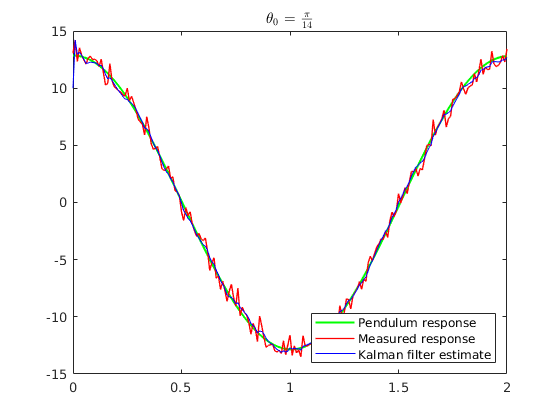


% Plot system response
figure(5);
plot(simOut.tout, simOut.theta.signals(1).values, 'g', LineWidth = 1.5);
hold on;
plot(simOut.tout, simOut.theta.signals(2).values, 'r', LineWidth = 1);
hold on;
plot(simOut.tout, simOut.theta.signals(3).values, 'b', LineWidth = 0.5);
title('$\theta_0$ = $\frac{\pi}{14}$', 'interpreter','latex');
legend('Pendulum response', 'Measured response', 'Kalman filter estimate', 'Location','southeast');
hold off;

### R estimation

% Pendulum rest position: theta0 = 0, theta_dot0 = 0
% Set parameters
model.simTime = 10;
set_param("virtualPendulumModel/Process noise", "Cov", "0");
set_param("virtualPendulumModel/rad2deg", "Gain", "1");
model.theta0 = 0;
model.theta_dot0 = 0;

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.0239
   -0.0039

EKF
    0.0239
   -0.0331

KF
    0.0022
   -1.0875

EKF
    0.0021
   -1.1070

KF
    0.0057
   -0.3701

EKF
    0.0056
   -0.3803

KF
    0.0020
   -0.3715

EKF
    0.0019
   -0.3765

KF
   -0.0029
   -0.4107

EKF
   -0.0030
   -0.4134

KF
   -0.0081
   -0.4395

EKF
   -0.0082
   -0.4413

KF
   -0.0062
   -0.2934

EKF
   -0.0062
   -0.2930

KF
   -0.0030
   -0.1691

EKF
   -0.0030
   -0.1667

KF
   -0.0020
   -0.1199

EKF
   -0.0019
   -0.1168

KF
   -0.0003
   -0.0727

EKF
   -0.0002
   -0.0687

KF
    0.0009
   -0.0434

EKF
    0.0010
   -0.0390

KF
   -0.0001
   -0.0515

EKF
   -0.0000
   -0.0479

KF
    0.0031
   -0.0010

EKF
    0.0033
    0.0041

KF
    0.0009
   -0.0305

EKF
    0.0010
   -0.0273

KF
   -0.0051
   -0.1019

EKF
   -0.0051
   -0.1026

KF
   -0.0084
   -0.1303

EKF
   -0.0085
   -0.1326

KF
   -0.0030
   -0.0469

EKF
   -0.0029
   -0.0446

KF
   -0.0037
   -0.0490

EKF
   -0.0036
   -0.0471

KF
   -0.0054
   -0.0640

EKF
   -0.0054
   -0


% Compute sample mean
model.R_est.sample_mean = 0;
for i = 1:length(simOut.theta.signals(2).values)

    model.R_est.sample_mean = model.R_est.sample_mean + simOut.theta.signals(2).values(i);
end
model.R_est.sample_mean = model.R_est.sample_mean / length(simOut.theta.signals(2).values);

% Compute sample variance
model.R_est.sample_variance = 0;
for i = 1:length(simOut.theta.signals(2).values)

    model.R_est.sample_variance = model.R_est.sample_variance + (simOut.theta.signals(2).values(i) - model.R_est.sample_mean)^2;
end
model.R_est.sample_variance = model.R_est.sample_variance / length(simOut.theta.signals(2).values);

### Effect of R on KF output

% R = 1e-4
% Set parameters
model.R = 1e-4;
model.simTime = 5;
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");
set_param("virtualPendulumModel/rad2deg", "Gain", "180/pi");
model.theta0 = pi/18;

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.1983
   -0.0192

EKF
    0.1983
   -0.0145

KF
    0.1765
   -1.1226

EKF
    0.1765
   -1.1193

KF
    0.1795
   -0.4255

EKF
    0.1795
   -0.4242

KF
    0.1752
   -0.4455

EKF
    0.1752
   -0.4446

KF
    0.1695
   -0.5023

EKF
    0.1695
   -0.5018

KF
    0.1634
   -0.5484

EKF
    0.1634
   -0.5481

KF
    0.1642
   -0.4192

EKF
    0.1642
   -0.4175

KF
    0.1662
   -0.3117

EKF
    0.1662
   -0.3083

KF
    0.1658
   -0.2792

EKF
    0.1658
   -0.2752

KF
    0.1659
   -0.2484

EKF
    0.1659
   -0.2437

KF
    0.1653
   -0.2354

EKF
    0.1654
   -0.2304

KF
    0.1624
   -0.2594

EKF
    0.1625
   -0.2553

KF
    0.1636
   -0.2248

EKF
    0.1637
   -0.2191

KF
    0.1591
   -0.2699

EKF
    0.1592
   -0.2661

KF
    0.1507
   -0.3566

EKF
    0.1508
   -0.3568

KF
    0.1448
   -0.4002

EKF
    0.1448
   -0.4018

KF
    0.1476
   -0.3316

EKF
    0.1477
   -0.3287

KF
    0.1441
   -0.3483

EKF
    0.1442
   -0.3459

KF
    0.1394
   -0.3776

EKF
    0.1394
   -0

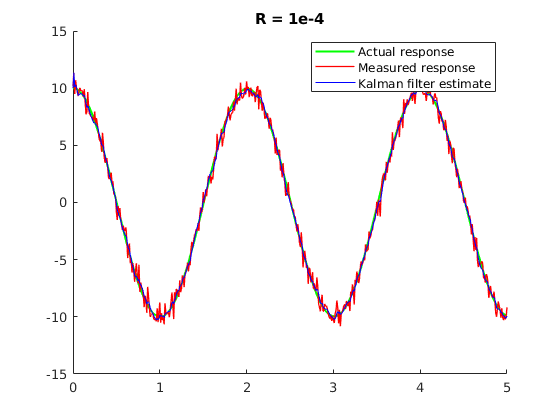

figure(6);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('R = 1e-4');
legend("Actual response","Measured response","Kalman filter estimate");

% R = 1e-3
% Set parameters
model.R = 1e-3;
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.2498
   -0.0238

EKF
    0.2498
   -0.0090

KF
    0.1960
   -0.5294

EKF
    0.1960
   -0.5313

KF
    0.2006
   -0.3515

EKF
    0.2006
   -0.3506

KF
    0.1900
   -0.5474

EKF
    0.1900
   -0.5476

KF
    0.1748
   -0.8095

EKF
    0.1748
   -0.8105

KF
    0.1571
   -1.0471

EKF
    0.1571
   -1.0490

KF
    0.1573
   -0.8406

EKF
    0.1573
   -0.8402

KF
    0.1628
   -0.5975

EKF
    0.1628
   -0.5935

KF
    0.1633
   -0.5059

EKF
    0.1633
   -0.5002

KF
    0.1659
   -0.4049

EKF
    0.1660
   -0.3968

KF
    0.1673
   -0.3453

EKF
    0.1675
   -0.3355

KF
    0.1622
   -0.3823

EKF
    0.1624
   -0.3743

KF
    0.1694
   -0.2681

EKF
    0.1698
   -0.2546

KF
    0.1605
   -0.3530

EKF
    0.1608
   -0.3447

KF
    0.1409
   -0.5348

EKF
    0.1409
   -0.5384

KF
    0.1286
   -0.6162

EKF
    0.1284
   -0.6248

KF
    0.1406
   -0.4616

EKF
    0.1408
   -0.4550

KF
    0.1357
   -0.4786

EKF
    0.1359
   -0.4728

KF
    0.1277
   -0.5185

EKF
    0.1278
   -0

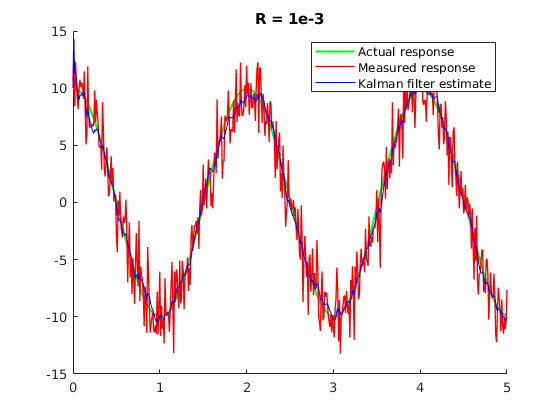

figure(7);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('R = 1e-3');
legend("Actual response","Measured response","Kalman filter estimate");

% R = 1e-5
% Set parameters
model.R = 1e-5;
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.1820
   -0.0178

EKF
    0.1820
   -0.0162

KF
    0.1723
   -0.8970

EKF
    0.1723
   -0.8961

KF
    0.1751
   -0.2236

EKF
    0.1751
   -0.2229

KF
    0.1735
   -0.2125

EKF
    0.1735
   -0.2119

KF
    0.1713
   -0.2332

EKF
    0.1713
   -0.2327

KF
    0.1688
   -0.2552

EKF
    0.1688
   -0.2548

KF
    0.1684
   -0.2160

EKF
    0.1684
   -0.2150

KF
    0.1683
   -0.1844

EKF
    0.1684
   -0.1830

KF
    0.1673
   -0.1823

EKF
    0.1674
   -0.1808

KF
    0.1664
   -0.1795

EKF
    0.1664
   -0.1780

KF
    0.1651
   -0.1846

EKF
    0.1651
   -0.1831

KF
    0.1628
   -0.2104

EKF
    0.1629
   -0.2094

KF
    0.1621
   -0.1972

EKF
    0.1621
   -0.1959

KF
    0.1588
   -0.2409

EKF
    0.1588
   -0.2403

KF
    0.1538
   -0.3142

EKF
    0.1538
   -0.3145

KF
    0.1498
   -0.3468

EKF
    0.1498
   -0.3474

KF
    0.1500
   -0.2821

EKF
    0.1500
   -0.2815

KF
    0.1469
   -0.3025

EKF
    0.1469
   -0.3020

KF
    0.1431
   -0.3335

EKF
    0.1431
   -0

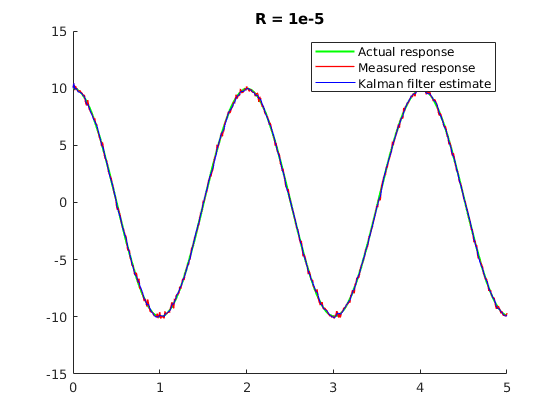

figure(8);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('R = 1e-5');
legend("Actual response","Measured response","Kalman filter estimate");

### Effect of Q on KF output

% Q = diag([0 1e-3]);
% Set parameters
model.R = 1e-4;
model.Q = diag([0 1e-3]);
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.1983
   -0.0192

EKF
    0.1983
   -0.0145

KF
    0.1765
   -1.1226

EKF
    0.1765
   -1.1193

KF
    0.1795
   -0.4255

EKF
    0.1795
   -0.4242

KF
    0.1752
   -0.4455

EKF
    0.1752
   -0.4446

KF
    0.1695
   -0.5023

EKF
    0.1695
   -0.5018

KF
    0.1634
   -0.5484

EKF
    0.1634
   -0.5481

KF
    0.1642
   -0.4192

EKF
    0.1642
   -0.4175

KF
    0.1662
   -0.3117

EKF
    0.1662
   -0.3083

KF
    0.1658
   -0.2792

EKF
    0.1658
   -0.2752

KF
    0.1659
   -0.2484

EKF
    0.1659
   -0.2437

KF
    0.1653
   -0.2354

EKF
    0.1654
   -0.2304

KF
    0.1624
   -0.2594

EKF
    0.1625
   -0.2553

KF
    0.1636
   -0.2248

EKF
    0.1637
   -0.2191

KF
    0.1591
   -0.2699

EKF
    0.1592
   -0.2661

KF
    0.1507
   -0.3566

EKF
    0.1508
   -0.3568

KF
    0.1448
   -0.4002

EKF
    0.1448
   -0.4018

KF
    0.1476
   -0.3316

EKF
    0.1477
   -0.3287

KF
    0.1441
   -0.3483

EKF
    0.1442
   -0.3459

KF
    0.1394
   -0.3776

EKF
    0.1394
   -0

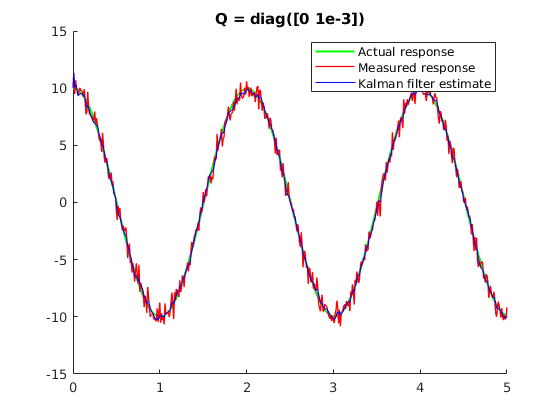

figure(9);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('Q = diag([0 1e-3])');
legend("Actual response","Measured response","Kalman filter estimate");

% Q = diag([0 1e-2]);
% Set parameters
model.Q = diag([0 1e-2]);
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.1983
   -0.0192

EKF
    0.1983
   -0.0145

KF
    0.1764
   -1.1287

EKF
    0.1764
   -1.1255

KF
    0.1795
   -0.4214

EKF
    0.1795
   -0.4201

KF
    0.1752
   -0.4422

EKF
    0.1753
   -0.4414

KF
    0.1696
   -0.5009

EKF
    0.1696
   -0.5004

KF
    0.1635
   -0.5489

EKF
    0.1635
   -0.5487

KF
    0.1645
   -0.4003

EKF
    0.1645
   -0.3987

KF
    0.1668
   -0.2694

EKF
    0.1668
   -0.2663

KF
    0.1667
   -0.2288

EKF
    0.1667
   -0.2254

KF
    0.1671
   -0.1856

EKF
    0.1672
   -0.1819

KF
    0.1669
   -0.1671

EKF
    0.1670
   -0.1636

KF
    0.1638
   -0.2146

EKF
    0.1638
   -0.2123

KF
    0.1659
   -0.1388

EKF
    0.1659
   -0.1358

KF
    0.1604
   -0.2435

EKF
    0.1605
   -0.2425

KF
    0.1496
   -0.4422

EKF
    0.1496
   -0.4441

KF
    0.1427
   -0.5128

EKF
    0.1426
   -0.5153

KF
    0.1489
   -0.2764

EKF
    0.1490
   -0.2749

KF
    0.1453
   -0.3095

EKF
    0.1453
   -0.3085

KF
    0.1398
   -0.3766

EKF
    0.1398
   -0

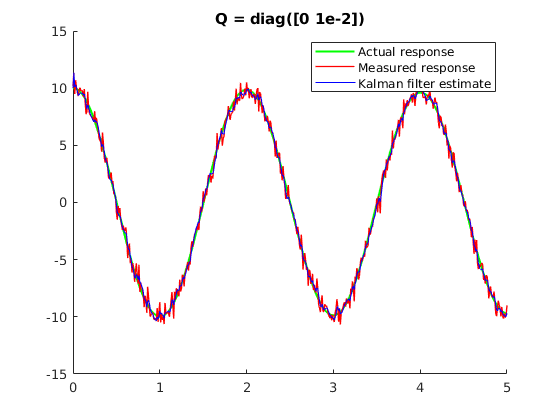

figure(10);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('Q = diag([0 1e-2])');
legend("Actual response","Measured response","Kalman filter estimate");

% Q = diag([0 1e-4]);
% Set parameters
model.Q = diag([0 1e-4]);
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.1983
   -0.0192

EKF
    0.1983
   -0.0145

KF
    0.1765
   -1.1221

EKF
    0.1765
   -1.1188

KF
    0.1795
   -0.4261

EKF
    0.1795
   -0.4248

KF
    0.1752
   -0.4461

EKF
    0.1752
   -0.4452

KF
    0.1695
   -0.5028

EKF
    0.1695
   -0.5023

KF
    0.1634
   -0.5487

EKF
    0.1634
   -0.5484

KF
    0.1642
   -0.4216

EKF
    0.1642
   -0.4198

KF
    0.1661
   -0.3167

EKF
    0.1661
   -0.3132

KF
    0.1656
   -0.2853

EKF
    0.1657
   -0.2813

KF
    0.1657
   -0.2564

EKF
    0.1657
   -0.2516

KF
    0.1651
   -0.2449

EKF
    0.1652
   -0.2396

KF
    0.1622
   -0.2670

EKF
    0.1623
   -0.2626

KF
    0.1632
   -0.2391

EKF
    0.1633
   -0.2330

KF
    0.1588
   -0.2773

EKF
    0.1589
   -0.2730

KF
    0.1508
   -0.3465

EKF
    0.1509
   -0.3462

KF
    0.1452
   -0.3826

EKF
    0.1452
   -0.3840

KF
    0.1472
   -0.3425

EKF
    0.1474
   -0.3390

KF
    0.1437
   -0.3577

EKF
    0.1438
   -0.3546

KF
    0.1392
   -0.3800

EKF
    0.1393
   -0

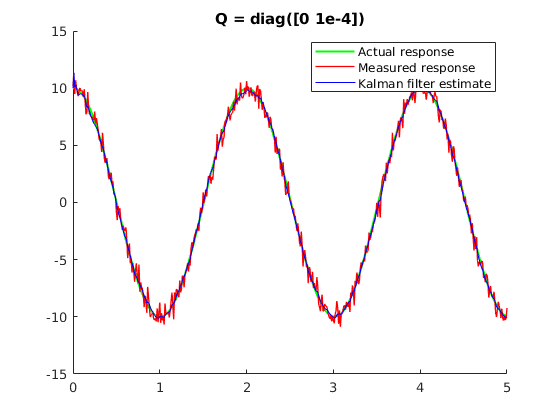

figure(11);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('Q = diag([0 1e-4])');
legend("Actual response","Measured response","Kalman filter estimate");

### **Large initial angle : 20deg**

% Set parameters
model.simTime = 5;
model.theta0 = deg2rad(40);
model.Q = diag([0 1e-3]);
model.R = 1e-4;
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");


% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

KF
    0.7216
   -0.0653

EKF
    0.7216
    0.0413

KF
    0.6992
   -1.2260

EKF
    0.6995
   -1.1487

KF
    0.7011
   -0.5859

EKF
    0.7015
   -0.5414

KF
    0.6951
   -0.6587

EKF
    0.6954
   -0.6290

KF
    0.6873
   -0.7658

EKF
    0.6876
   -0.7419

KF
    0.6787
   -0.8608

EKF
    0.6789
   -0.8388

KF
    0.6765
   -0.7800

EKF
    0.6767
   -0.7566

KF
    0.6749
   -0.7203

EKF
    0.6752
   -0.6945

KF
    0.6706
   -0.7351

EKF
    0.6709
   -0.7074

KF
    0.6663
   -0.7512

EKF
    0.6667
   -0.7212

KF
    0.6609
   -0.7845

EKF
    0.6614
   -0.7526

KF
    0.6527
   -0.8544

EKF
    0.6532
   -0.8218

KF
    0.6481
   -0.8649

EKF
    0.6488
   -0.8295

KF
    0.6374
   -0.9545

EKF
    0.6382
   -0.9196

KF
    0.6225
   -1.0851

EKF
    0.6232
   -1.0527

KF
    0.6096
   -1.1716

EKF
    0.6103
   -1.1400

KF
    0.6049
   -1.1452

EKF
    0.6058
   -1.1092

KF
    0.5936
   -1.2033

EKF
    0.5946
   -1.1676

KF
    0.5806
   -1.2730

EKF
    0.5816
   -1

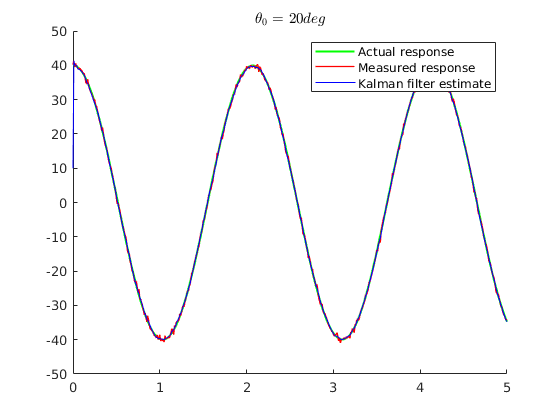

figure(12);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('$\theta_0$ = $20 deg$', 'interpreter','latex');
legend("Actual response","Measured response","Kalman filter estimate");

### Linear response vs NL response

model.theta0 = deg2rad(5);
sys = ss(model.dis_lin.A, model.dis_lin.B, model.dis_lin.C, model.dis_lin.D, model.ts);
set_param('virtualPendulumModel/Process noise','Cov','0');
tfinal = 10;
[y,t] = initial(sys,[model.theta0;0], 0:model.ts:tfinal);
simOut = sim("models/virtualPendulumModel", tfinal);

KF
    0.1111
   -0.0115

EKF
    0.1111
   -0.0238

KF
    0.0893
   -1.1052

EKF
    0.0893
   -1.1133

KF
    0.0926
   -0.3980

EKF
    0.0925
   -0.4026

KF
    0.0886
   -0.4089

EKF
    0.0885
   -0.4110

KF
    0.0833
   -0.4569

EKF
    0.0832
   -0.4581

KF
    0.0776
   -0.4944

EKF
    0.0776
   -0.4953

KF
    0.0790
   -0.3568

EKF
    0.0790
   -0.3559

KF
    0.0815
   -0.2409

EKF
    0.0816
   -0.2382

KF
    0.0819
   -0.2001

EKF
    0.0819
   -0.1967

KF
    0.0827
   -0.1611

EKF
    0.0828
   -0.1569

KF
    0.0831
   -0.1400

EKF
    0.0831
   -0.1354

KF
    0.0811
   -0.1561

EKF
    0.0812
   -0.1524

KF
    0.0833
   -0.1135

EKF
    0.0834
   -0.1083

KF
    0.0799
   -0.1508

EKF
    0.0800
   -0.1476

KF
    0.0727
   -0.2300

EKF
    0.0727
   -0.2306

KF
    0.0681
   -0.2660

EKF
    0.0681
   -0.2681

KF
    0.0722
   -0.1900

EKF
    0.0723
   -0.1876

KF
    0.0701
   -0.1994

EKF
    0.0702
   -0.1975

KF
    0.0669
   -0.2216

EKF
    0.0669
   -0

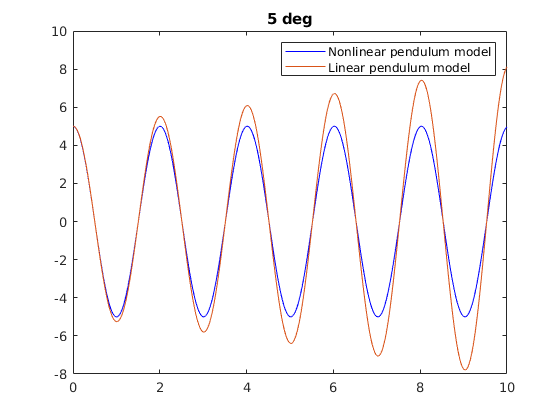

figure(13);
plot(simOut.tout,simOut.theta.signals(1).values,'b');
hold on;
plot(t,rad2deg(y))
title('5 deg');
legend('Nonlinear pendulum model','Linear pendulum model')

model.theta0 = deg2rad(20);
[y,t] = initial(sys,[model.theta0;0], 0:model.ts:tfinal);
simOut = sim("models/virtualPendulumModel", tfinal);

KF
    0.3727
   -0.0346

EKF
    0.3727
    0.0041

KF
    0.3507
   -1.1578

EKF
    0.3508
   -1.1311

KF
    0.3533
   -0.4809

EKF
    0.3534
   -0.4672

KF
    0.3484
   -0.5196

EKF
    0.3485
   -0.5117

KF
    0.3420
   -0.5940

EKF
    0.3420
   -0.5888

KF
    0.3349
   -0.6572

EKF
    0.3350
   -0.6533

KF
    0.3347
   -0.5447

EKF
    0.3347
   -0.5398

KF
    0.3354
   -0.4538

EKF
    0.3355
   -0.4474

KF
    0.3336
   -0.4376

EKF
    0.3337
   -0.4307

KF
    0.3321
   -0.4229

EKF
    0.3322
   -0.4153

KF
    0.3298
   -0.4259

EKF
    0.3300
   -0.4178

KF
    0.3250
   -0.4658

EKF
    0.3252
   -0.4585

KF
    0.3241
   -0.4468

EKF
    0.3243
   -0.4378

KF
    0.3175
   -0.5073

EKF
    0.3176
   -0.5001

KF
    0.3068
   -0.6092

EKF
    0.3069
   -0.6057

KF
    0.2984
   -0.6677

EKF
    0.2984
   -0.6656

KF
    0.2985
   -0.6138

EKF
    0.2987
   -0.6072

KF
    0.2922
   -0.6448

EKF
    0.2924
   -0.6387

KF
    0.2846
   -0.6881

EKF
    0.2847
   -0

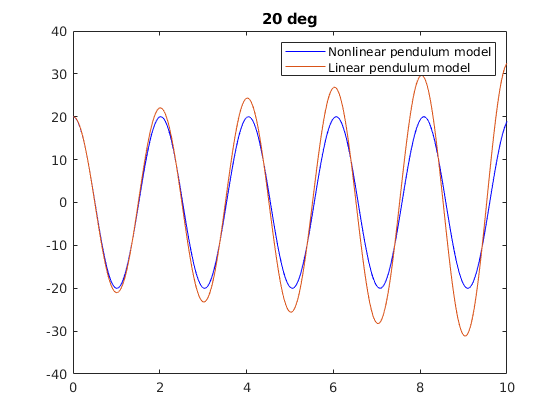

figure(14);
plot(simOut.tout,simOut.theta.signals(1).values,'b');
hold on;
plot(t,rad2deg(y))
title('20 deg');
legend('Nonlinear pendulum model','Linear pendulum model')

set_param('virtualPendulumModel/Process noise','Cov','model.Q(2,2)*model.ts');

## Extended Kalman Filter to estimate the angular position of the nonlinear pendulum system

To implement an extended Kalman filter and compare it to the previously designed Kalman filter, complete the following steps:

- Add an Extended Kalman Filter block to the model. Use the same inputs you used for the linear Kalman filter and connect T and measured theta to **StateTransitionFcnInputs** and **y1** inports of the Extended Kalman Filter, respectively. 

- Extended Kalman Filter block computes estimates of a discrete nonlinear system. So, you need to use the [Zero-Order Hold](https://www.mathworks.com/help/simulink/slref/zeroorderhold.html) block to descretize the input torque and the measured theta. In the zero-order hold block, enter a sample time of 0.01. Use a [Selector](https://www.mathworks.com/help/simulink/slref/selector.html) block to connect theta estimated by the Extended Kalman Filter (first element of xhat) to the mux block and configure demux block to output all fours signals. Label the signals as seen in the above picture. 

**Task 17. **Double-click the Extended Kalman Filter to view the required functions and parameters you need to specify for designing the filter. As seen under the **System Model** tab in the block dialog, the Extended Kalman filter requires a discrete-time state transition function that describes the evolution of system states from one time step to the next. The filter also needs a measurement function that describes how the states are related to measurements. Next, you will create these functions and specify them in the block dialog along with other required parameters such as covariances.

**State Transition Function**

To compute the discrete-time state transition function, you need to first discretize the continuous-time state equations of the nonlinear pendulum model that are given below.  


$$\begin{array}{l}
{\dot{x} }_1 =x_2 \\
{\dot{x} }_2 =-\frac{g}{L}\sin \left(x_1 \right)+\frac{u}{{\textrm{mL}}^2 }
\end{array}$$


where $x_1 =\theta$ and $x_2 =\dot{\theta}$.

Compute the discrete-time state equations by discretizing the above state equations using Euler discretization which approximates the derivative operator as $\dot{x} \approx \frac{x_{n+1} -x_n }{T_s }$ ($T_s$ is the discrete sampling period). Write the discrete-time state equations in the following form:


$$\begin{array}{l}
x_1 \left\lbrack k+1\right\rbrack =\textrm{Complete}\;\textrm{rest}\;\textrm{of}\;\textrm{the}\;\textrm{equation}\\
x_2 \left\lbrack k+1\right\rbrack =\textrm{Complete}\;\textrm{rest}\;\textrm{of}\;\textrm{the}\;\textrm{equation}
\end{array}$$


**Task 18.** [myStateTransitionFcn](matlab:open('/myStateTransitionFcn.m')) is the state transition function that is used by the Extended Kalman Filter. Open [myStateTransitionFcn](matlab:open('/myStateTransitionFcn.m')) and complete it by writing code to define the discrete-time state equations you've found above. The state transition function you've just created is specified under **System Model >** **State Transition > Function** in the Extended Kalman Filter block dialog. You can provide an analytical Jacobian for the state transition function. If an analytical Jacobian is not provided, the extended Kalman filter algorithm computes the Jacobian numerically. You can use the default setting for the process noise as the pendulum model has an additive process noise. Set the process noise covariance to diag([0 1e-3]), and the initial states to [pi/2 0]. Set the initial covariance for the state estimation error to a small value such as 1e-3. Note that if you don't have confidence in the initial state values, you need to specify a high value for the initial covariance.

**Task 19. ****Measurement Function****: **The filter also needs a measurement function that describes how the states are related to measurements. The continuous-time measurement function of the pendulum model is given below.


$$y=x_1$$


[myMeasurementFcn](matlab:open('/myMeasurementFcn.m')) is the measurement function that is used by the Extended Kalman Filter. Open [myMeasurementFcn](matlab:open('/myMeasurementFcn.m')) and complete it by writing code to define the measurement equation given above. The measurement function is specified under **System Model > State Transition > Measurement** **1 **in the Extended Kalman Filter block dialog. You can provide an analytical Jacobian of the state transition function for the state transition function. If an analytical Jacobian is not provided, the extended Kalman filter algorithm computes the Jacobian numerically. You can use the default setting for the measurement noise which is set to additive noise. Set the measurement noise covariance to 1e-4, and specify a sample time of 0.01 under Settings > Sample time and click OK.

**Task 20. **Once you're done with the design of the extended Kalman filter, set initial states, Q and R of the Kalman filter to the same values you used in the Extended Kalman filter (initial state = [pi/2 0], Q = diag([0,1e-3]), R = 1e-4). Set pendulum's initial angle to 90 degrees by pressing the button below. Finally, run the Simulink model and open the scope to view the simulation results. Insert a snapshot of scope results below. 

 
theta0 = pi/2;

*Insert a snapshot of the simulation results here*

Are you able to get a good estimate with the extended Kalman filter? How does the extended Kalman filter estimate compare to the estimate computed by the linear Kalman filter?

task20 = "<Replace this text with your answer but keep the quotes>"

task20 = "<Replace this text with your answer but keep the quotes>"

model.theta0 = deg2rad(90);